## Problem 1.

다음과 같이 1차 ARX model을 고려하자

$y(t) - 0.9y(t-1) = b_0 u(t) + \nu(t)$, $b_0 =\left\lbrace \begin{array}{ll}
1\ldotp 5 & t\le \frac{N}{2}\\
0\ldotp 5 & t>\frac{N}{2}
\end{array}\right.$

이때 N = 400이고, noise $\nu$는 $N(0, 0.1^2)$을 따른다고 하자.

clc; close all; clear all;

### a)

$t = [0, N/2]$ 시간 동안 batch data에 대해 1차 ARX 모델을 추정하기 위한 LSM solution $\left(\hat{a} ,\hat{b} \right)$를 구하라

***sol)***

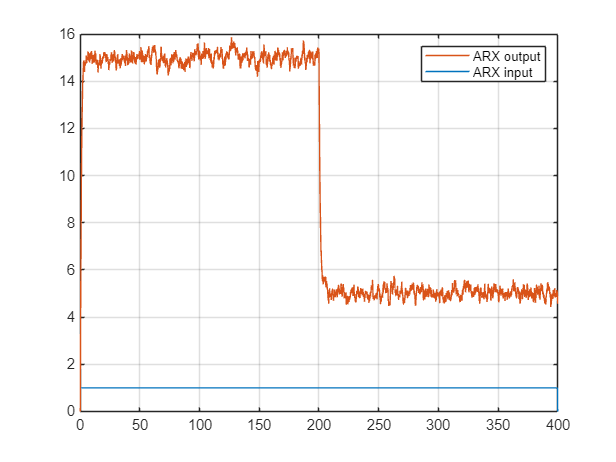

rng(0);
% ARX_model
timestep_T = 0.1;
N = 400;
time = linspace(0, N, N/timestep_T + 1);
output_data = zeros([length(time), 1]);
input_data = zeros([length(time), 1]);

output_y = 0;       % y(t)
prev_output_y = 0;  % y(t-1)
input_u = 1;        % Unit step input
noise_nu = 0.1;     % Gaussian noise with zero mean, 0.1 std

for t = 1 : length(time)
    if (t + 1 > length(time))
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    output_data(t+1) = output_y;
    input_data(t) = input_u;
    prev_output_y = output_y;
end

Input = plot(time, input_data);
hold on; grid on;
Output = plot(time, output_data);
legend([Output, Input], {"ARX output", "ARX input"});
hold off;

위의 loop를 토대로 y(0) = 0이라는 initial condition 가정을 세우고, LSM에 사용할 수 있는 output y의 data를 `y(2:end, :)`까지 얻을 수 있다. 위 코드는 unit step input에 대해서 ARX 모델이 noise $N(0, 0.1^2)$을 포함한 output 데이터를 획득하기 위해서 작성됐다. 이를 바탕으로 LSM solution $\left(\hat{a} ,\hat{b} \right)$을 도출할 수 있다.


$$\begin{array}{l}
Y={\left\lbrack \begin{array}{cccc}
y\left(2\right) & y\left(3\right) & \cdots \; & y\left(n\right)
\end{array}\right\rbrack }^T \\
Y^- ={\left\lbrack \begin{array}{cccc}
y\left(1\right) & y\left(2\right) & \cdots \; & y\left(n-1\right)
\end{array}\right\rbrack }^T \\
U={\left\lbrack \begin{array}{cccc}
u\left(2\right) & u\left(3\right) & \cdots \; & u\left(n\right)
\end{array}\right\rbrack }^T \\
\hat{\Theta} ={\left\lbrack \begin{array}{cc}
\hat{a}  & \hat{b} 
\end{array}\right\rbrack }^T \\
\hat{\Theta} ={\left({\left\lbrack \begin{array}{cc}
Y^-  & U
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{cc}
Y^-  & U
\end{array}\right\rbrack \right)}^{-1} {\left\lbrack \begin{array}{cc}
Y^-  & U
\end{array}\right\rbrack }^T Y\;
\end{array}$$


Y = output_data(2:end, :);
Y_ = output_data(1:end-1, :);
U = input_data(2:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.9993
    0.0079


$t \leq N/2$의 데이터만으로 LSM을 진행했을 때 $\hat{b}_0$와 $\hat{a}_0$의 추정이 모두 원래의 값과 비슷한 것을 확인할 수 있다.

Y = output_data(2:(length(output_data)-1)/2, :);
Y_ = output_data(1:(length(output_data)-1)/2-1, :);
U = input_data(2:(length(output_data)-1)/2, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.8961
    1.5578


마찬가지로 $t > N/2$의 데이터만으로 LSM을 진행했을 때 $\hat{b}_0$와 $\hat{a}_0$의 추정이 모두 원래의 값과 비슷한 것을 확인할 수 있다.

Y = output_data((length(output_data)-1)/2+1:end, :);
Y_ = output_data((length(output_data)-1)/2:end-1, :);
U = input_data((length(output_data)-1)/2+1:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.9176
    0.4141


위처럼 중간에 $b_0$가 변하는 상황에선** LTI(Linear time invariance) 가정이 어긋나**기에 LSM을 적용했을 때 $\hat{b}_0$는 아래의 두 추정보다 상대적으로 더 오차가 큰 모습을 확인할 수 있고, $\hat{a}_0$는 그 중간에도 미치지 못한 모습을 확인할 수 있다.

Sinusoidal input에 대해서도 LSM을 진행해 보았다.

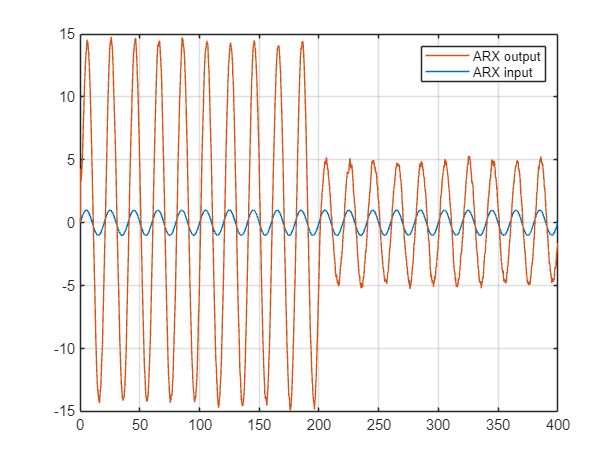

cycle_time = 20;
output_sinusoidal_data = zeros([length(time), 1]);
input_sinusoidal_u = sin(time.*(2*pi)./cycle_time)';
for t = 1 : length(time)
    if (t + 1 > length(time))
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_sinusoidal_u(t + 1) + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    output_sinusoidal_data(t+1) = output_y;
    prev_output_y = output_y;
end

Input = plot(time, input_sinusoidal_u);
hold on; grid on;
Output = plot(time, output_sinusoidal_data);
legend([Output, Input], {"ARX output", "ARX input"});
hold off;

Y = output_sinusoidal_data(2:end, :);
Y_ = output_sinusoidal_data(1:end-1, :);
U = input_sinusoidal_u(2:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.9726
    0.3363


$t \leq N/2$**의 데이터만으로 LSM을 진행**

Y = output_sinusoidal_data(2:(length(output_data)-1)/2, :);
Y_ = output_sinusoidal_data(1:(length(output_data)-1)/2-1, :);
U = input_sinusoidal_u(2:(length(output_data)-1)/2, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.8991
    1.5135


$t > N/2$**의 데이터만으로 LSM을 진행**

Y = output_sinusoidal_data((length(output_data)-1)/2+1:end, :);
Y_ = output_sinusoidal_data((length(output_data)-1)/2:end-1, :);
U = input_sinusoidal_u((length(output_data)-1)/2+1:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.8986
    0.5128


Sinusoidal input을 이용해 LSM을 진행했을 때도 마찬가지로 LTI 가정이 깨져 $t \leq N/2$, $t > N/2$ 각각의 데이터를 사용했을 때보다 한꺼번에 추정했을 때의 parameter 추정이 $0.5$ 근처에만 간 모습을 확인할 수 있다.

## b)

Initial parameter와 초기 covariance를 다음과 같이 설정하였다고 하였을 때, $\rho =\left\lbrack \begin{array}{ccc}
0\ldotp 1 & 1 & 10
\end{array}\right\rbrack$ 에 따른 recursive estimator를 설계하여라. $t=[0, N/2]$에 대한 $y$의 시간반응을 그래프로 나타내고, a) 결과와 비교하여라. 또한, $\rho$에 따른 그래프의 경향성을 분석하여라.


$$\hat{\theta \;} \left(0\right)=0,\;\;\;P\left(0\right)=\rho \;\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


***sol)***